## Low pass - variable bandwith - filter

#### **forked from:**

#### **"Understanding CIC Compensation Filters"**

by ALTERA Application Note 455

This low pass - variable bandwith - filter is composed by a CIC decimating filter and a FIR compensating filter.

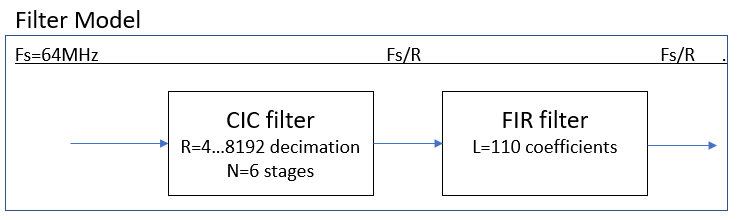

In this document I describe the design and magnitude response.

At first, set the CIC filter parameters:

R = 4;     %% Decimation factor. Can range from 4 to 8192
M = 1;     %% Differential delay. it is always 1
N = 6;     %% Number of stages.
B = 16;    %% Coefficients bit-width
Fs = 64e6; %% Sampling freq in Hz before decimation


and buld the CIC filter with 0 Hz amplification = 0dB:

cicdecim = dsp.CICDecimator(...
    'DecimationFactor',R,...
    'NumSections',N);
decimcasc = dsp.FilterCascade(cicdecim,...
    1/gain(cicdecim));

then set the FIR parameters:

L = 110; %% Filter order; must be even
%Fo = R*Fc/Fs; %% Normalized Cutoff freq; 0<Fo<=0.5/M;
% Fo = 0.5/M; %% use Fo=0.5 if you don't care responses are
Fo = 0.25; % Normalized Cutoff freq

and create the FIR filter compensating the CIC filter, using dsp.fir2:

 b = firceqrip(L,Fo,[0.02 10e-7],'invsinc',[0.5 8]);

where:

0.02 is the maximum bandpass ripplle

10e-7 is the stopband attenuation i.e. -140 dB but the result is -120dB

b are the 111 coefficients

0 Hz amplification = 0dB

fircomp_gain = dsp.FIRFilter(b);
%fircomp = dsp.FilterCascade(fircomp_gain, 1/sum(b));
fircomp = dsp.FIRFilter(b);

Write the FIR coefficients to a XILINX compatible file

hq = dfilt.dffir(b/sum(b)); 
set(hq,'arithmetic','fixed'); 
cd('D:\EBAZ4205_SDR\matlab\');
coewrite(hq,10,'mycoefile');


Finally create the CIC + FIR filter:

% Create the CIC + FIR filter
cicfir = dsp.FilterCascade(decimcasc, fircomp);


Show the three filters:

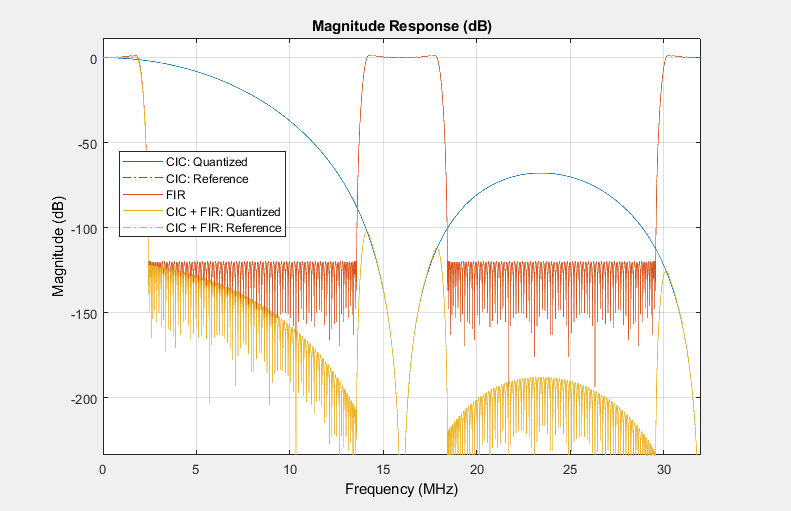

% view the three filters
myfv = fvtool(decimcasc, fircomp, cicfir, 'Fs', [Fs, Fs/R, Fs]);
legend(myfv, "CIC", "FIR", "CIC + FIR");  